clearvars;

### Initial parameter

f = 440; % Hz
c = 343; % m/s
k = 2*pi*f/c; % Wave number

## Spherical Harmonics

The purpose of this script is to research how an input pressure can be represented in spherical harmonics and how a spherical harmonics representation can be translated to an output pressure.

### Spherical Harmonics - Sound pressure

The sound pressure at a point $x\{r,\theta,\phi\}$ with respect to the origin can be expressed as


$$P(r,\theta,\phi,k) = \sum_{l=0}^\infty \sum_{m=-l}^l C_{lm}(k)j_l(kr)Y_{lm}(\theta,\phi)$$


where

$C_{lm}(k)$ are the spherical harmonics coefficients,

$k=\frac{2\pi f}{c}$ is the wave number,

$f$ is the frequency,

$c$  is the speed of sound propagation

$j_l(kr)$ is the $l$th order Bessel function of the first kind,

$Y_{lm}(\theta,\phi)$ are the spherical harmonics.

#### Bessel function

l = 1, m = 1; r = 1; % Meaningless values for degree, order, radius

l = 1

J = besselj(l,k*r);

#### Spherical Bessel function

sphbessel(l,k*r);

#### Spherical harmonics

The spherical harmonic of degree $l$ and order $m$ is given by


$$Y_{lm}(\theta,\phi) \equiv (-1)^m \sqrt{\frac{2l+1}{4\pi}\frac{(l-m)!}{(l+m)!}}P_l^m(\cos(\theta))e^{im\phi}$$


where 

$P_n^m(x)$ is the associated Legendre function, unnormalized.

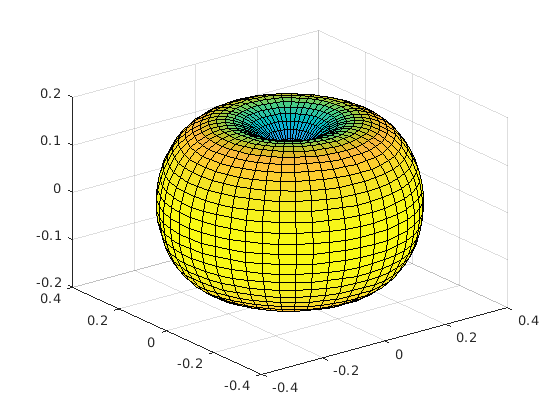

% create a 2D grid
th = linspace(0,pi,50);    % inclination
phi = linspace(0,2*pi,50); % azimuth
[th,phi] = meshgrid(th,phi);

% compute spherical harmonic of degree 3 and order 1
Y = harmonicY(l,m,th,phi);

% plot the magnitude
[x,y,z] = sph2cart(phi,pi/2-th,abs(Y));
surf(x,y,z,abs(Y));

### Approximation

The sound field can be approximated by


$$P(r,\theta,\phi,k) = \sum_{l=0}^L \sum_{m=-l}^l C_{lm}(k)j_l(kr)Y_{lm}(\theta,\phi)$$


where


$$L = \lceil \frac{ekr}{2} \rceil$$


$e$ is the natural exponential

### Sound pressure - Harmonic Coefficients

We have 


$$P(r,\theta,\phi,k) = \sum_{l=0}^\infty \sum_{m=-l}^l C_{lm}(k)j_l(kr)Y_{lm}(\theta,\phi)$$


By multiplying both side by $\overline\mathbf{Y}_{lm}$ and integrating over the sphere we get:


$$C_{lm}(k) = \frac{1}{\mathbf j_l(kr)}\int_0^\pi\int_0^{2\pi}P(r,\theta,\phi,k)\overline\mathbf{Y}_{lm}(\theta,\phi)d\theta d\phi$$


where 

$\overline\mathbf{Y}_{lm}$ is the complex conjugate matrix of $\mathbf{Y}_{lm}$

#### Plane wave - Expansion in Spherical Harmonics

According to [https://en.wikipedia.org/wiki/Plane-wave_expansion](https://en.wikipedia.org/wiki/Plane-wave_expansion) as plane wave can be expressed as a linear combination of spherical harmonics:


$$e^{i\mathbf k \cdot \mathbf r} = 4 \pi \sum^\infty_{l=0}\sum_{m=-l}^l i^lj_l(kr)Y_{lm}(\mathbf \hat k)\overline{Y}_{lm}(\mathbf \hat r),$$


where

$i$ is the imaginary unit,

$\mathbf k$ is a wave vector of length $k$,

$\mathbf r$ is a position vector of length $r$,

$\mathbf \hat k = \frac{\mathbf k}{|\mathbf k|}$ and $\mathbf \hat r$ is the unit vector of $\mathbf k$ and $\mathbf r$ respectively.

in spherical coordinates  $\mathbf k\{\rho_k,\theta_k,\phi_k\}$ and  $\mathbf r\{\rho_r,\theta_r,\phi_r\}$.


$$e^{i \mathbf k \cdot \mathbf r} = 4 \pi \sum^\infty_{l=0}\sum_{m=-l}^l i^lj_l(\rho_k\rho_r)Y_{lm}(\theta_k,\phi_k,\rho_k)\overline{Y}_{lm}(\theta_r,\phi_r,\rho_r),$$


where 


$$\mathbf k \cdot \mathbf r = \rho_k\rho_r[\sin\theta_k\sin\theta_r\cos(\phi_k-\phi_2)+\cos\theta_k\cos\theta_r]$$


$\rho_k = \frac{2\pi}{\lambda} = \frac{2\pi f}{c}$,

$\lambda$ is the wave length.

clearvars;
f = 300; c = 343;
rho_r = 0.01:0.01:20; r = [rho_r;zeros(1,length(rho_r));zeros(1,length(rho_r))];
k = [2*pi*f/c;0;0]; rho_k = norm(k);
the_k = atan(k(2)/k(1)); phi_k = atan((k(1)^2+k(2)^2)/k(3));
the_r = max(atan(r(2,:)./r(1,:))); phi_r = max(atan((r(1,:).^2+r(2,:).^2)./r(3,:)));
nr = length(rho_r);

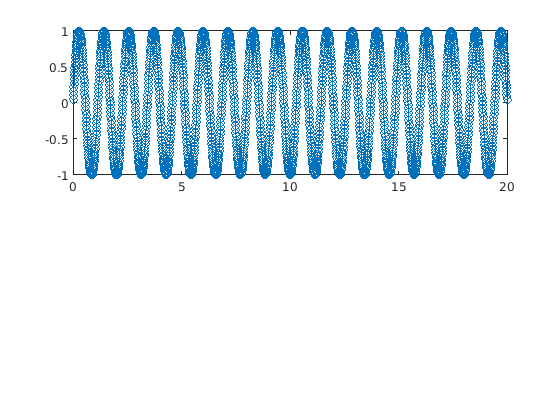

wave = exp(1i*myDot(k,r));
figure;
subplot(211)
plot(rho_r, imag(wave),'-o');

Harmonics Matrix

L = max(ceil((exp(1)*rho_k*rho_r/2)));
Yk = zeros(L+1,2*L+1);
Yr = Yk;
for l=0:L
    idxl = l+1;
    for m=-l:l
        idxm = m+idxl;
        Yk(idxl,idxm) = harmonicY(l,m,the_k,phi_k,1);
        Yr(idxl,idxm) = harmonicY(l,m,the_r,phi_r,1);
    end
end
cYr = conj(Yr);

Precalculate Summation Matrix in vectorized form.

l = 0:L; m = -L:L;
idxl = l+1; idxm = m+L+1;
nr = length(rho_r);
PP = zeros(length(l),length(m),nr);
for n=1:nr
    PP(:,:,n) = (1i.^(l+2)').*sphbessel(l',rho_k*rho_r(n)).*Yk(idxl,idxm,1).*cYr(idxl,idxm,1);
end

Why in this calculation we need $i^{l+2}$ is not quite clear...

But with $i^l$ the resulting wave is shifted by half a wave length.

Computing wave using spherical harmonics expansion

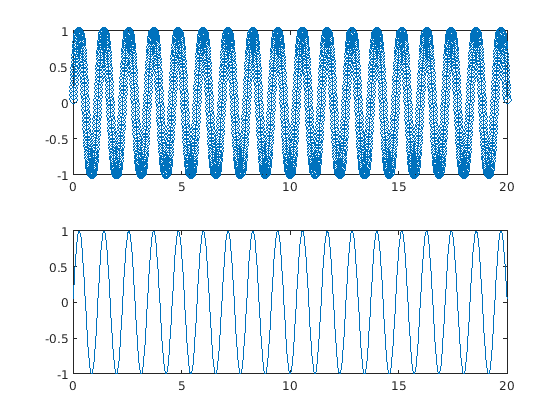

P = zeros(1,nr);
for n=1:nr
    for l=0:L
        idxl = l+1;
        for m=-l:l
            idxm = m+idxl;
            P(n) = P(n) + PP(idxl,idxm,n);
        end
    end
    
end
P = 4*pi*P;
subplot(212);
plot(rho_r,imag(P));

Computing wave with spherical harmonics using a loop. Slower...

% P = zeros(1,nr);
% h = waitbar(0,"initializing");
% L = max(ceil((exp(1)*rho_k*rho_r/2)));
% for n=1:nr
%     for l=0:L
%         idxl = l+1;
%         for m=-l:l
%             idxm = m+idxl;
%             P(n) = P(n) + 1i^l*sphbessel(l,rho_k*rho_r(n))*Yk(idxl,idxm,1)*cYr(idxl,idxm,1);
%         end
%     end
%     P(n) = P(n) * 4 * pi;
%     waitbar(n/nr,h,"loading");  
% end
% close(h);
% figure;
% plot(rho_r,imag(P));

### Harmonic Coefficient - Spherical Microphone array

$C_{lm}(k) = \frac{1}{j_l(kR)}\sum_iP(R,\theta_i,\phi_i,k)\overline Y_{lm}(\theta_i,\phi_i)\gamma_i$,

where

$\theta_i$ and $\phi_i$ are the elevation and azimuth of the $i$th microphone,

$\gamma_i$ are some weighting coefficients specific to the sampling scheme of the microphone array.

### Numerical Integration - Gauss-Legendre Quadrature on the sphere

According to [http://homepage.math.uiowa.edu/~atkinson/papers/SphereQuad1982.pdf](http://homepage.math.uiowa.edu/~atkinson/papers/SphereQuad1982.pdf)

an integral 


$$I(f) = \int_0^{2\pi}\int_0^\pi F(\theta,\phi) \sin \theta \,d \theta \,d \phi$$


can be approximated with


$$I_m(f) = \frac{\pi}{m}\sum^{2m}_{j=1}\sum_{i=1}^mw_if(\theta_i,\phi_i)$$


where

$\theta_i$ are chosen so that $\{\cos\theta_i\}$ and $\{w_i\}$ are the Gauss-Legendre nodes and weights on $[-1, 1]$. 

$\phi_i$ are evenly spaces on $[0,2\pi]$ with spacing $\frac{\pi}{m}$;

usually $\phi_j = j\frac{\pi}{m}$ or $\phi_j = \bigg(j-\frac{1}{2}\bigg)\frac{\pi}{m}$

$I_m(f)$ integrates exactly any polynomial of degree less than $2m$, therefore m should be no fewer than $\frac{1}{2}L$

According to [https://cbeentjes.github.io/files/Ramblings/QuadratureSphere.pdf](https://cbeentjes.github.io/files/Ramblings/QuadratureSphere.pdf) the integral over the unit sphere can be viewed as a product of two one-dimensional intergrals over $\theta$ and $\phi$.

$Q[f] = \sum_{i=0}^{N-1}w_i\sum_{j=0}^{M-1}v_jf(\theta_i,\phi_j) = \sum_{i=0}^{N-1}\sum_{j=0}^{M-1}\tilde w_{ij}f(\theta_i,\phi_j)$.

The weights $\tilde w_{ij}$ are determined by using an equally spaced schemes, such as the trapezoidal method in $\theta$ and the Gauss-Legendre scheme for $\phi$.

An equally spaced grid of $M$ points ensures exact integration of

$\int_0^{2\pi}e^{im\theta}\,d\theta$     for $|m| \leq M$

The Gauss-Legendres scheme of order $n$ garantees exact integration of all polynomials $p_l(x)$ up until degree $l = 2n -1$ over the interval $[-1,1]$.  This can be we rewritten to get the exact results for integrals of the form


$$\int_0^\pi p_l(\cos\phi)\sin\phi\,d\phi$$


To intergrate all spherical harmonics up until degree $p$ we would need $(p+1)/2$ points for the $\phi$ intergal and $(p+1)$ points for the $\theta$ integral resulting in a total of $(p+1)^2/2$ points.

According to "The fundamentals of Spherical Array Processing by Boaz Rafaely"

A function $f(\theta, \phi) \in L_2(S^2)$ can be represented using a weighted sum of spherical harmonics as


$$f(\theta,\phi) = \sum_{n=0}^\infty \sum_{m=-n}^n f_{nm}Y_n^m(\theta,\phi),$$


where $f_{nm}$ are the weigths. These weigths form the spherical Fourier transform of $f(\theta,\phi)$ and can be derived from $f(\theta,\phi)$ by


$$f_{nm} = \int_0^{2\pi}\int_0^{\pi}f(\theta,\phi)\overline Y_{n}^m(\theta,\phi)\sin\theta\,d\theta\,d\phi.$$


#### Gaussian Sampling

The spherical Fourier transform can be sampled using the gaussian sampling scheme and is given by


$$f_{nm} = \sum_{q=0}^N\sum_{l=0}^{2N+1}a_qf(\theta_q,\phi_l)\overline Y_n^m(\theta_q,\phi_l), \quad n \leq N.$$


When applying this on the harmonic coefficients we get


$$C_{lm}(k) = \frac{1}{j_l(kR)} \sum_{q=0}^N\sum_{l=0}^{2N+1}a_qP(R,\theta_q,\phi_l,k)\overline Y_{lm}(\theta_q,\phi_l)$$


where the weights are given by


$$a_q = \frac{\pi}{N+1}\frac{2(1-\cos^2\theta_q)}{(N+2)^2[P_{N+2}(\cos \theta_q)]^2}, \quad 0 \leq q\leq N$$


where the azimuth angle is sampled at $2(N+1)$ equal-angle samples:


$$\phi_l = l\frac{2\pi}{2N+2},\quad l=0,...,2N+1$$


The elevation angle is sampled by selecting $(N+1)$ samples that are the zeros of $P_{N+1}(\cos\theta)$,


$$P_{N+1}(\cos\theta_q)=0, \quad 0 \leq q \leq N$$


where 

$P_{N+1}$ is the legendre polynomial of degree $N+1$

which means a total number of samples/microphone of $2(N+1)^2$

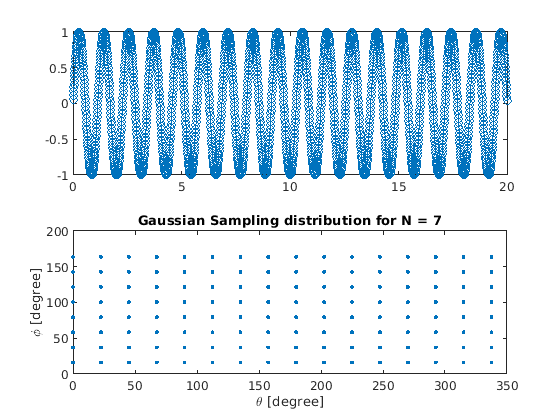

N = 7;
l = 0:(2*N+1);
phi_l = l*(2*pi)/(2*N+2);
theta_q = legendrePzeros(N);
[~,~] = plotSamples(N,phi_l,theta_q);

Calculating the weigths

a_q = pi./(N+1).*(2.*(1-cos(theta_q).^2))./((N+2)^2*legendreP(N+2,cos(theta_q)).^2);

For ease of calculation we transform the formula as well as the weight and angles to have only one counting variable $i$


$$C_{lm}(k) = \frac{1}{j_l(kR)}\sum_ia_iP(R,\theta_i,\phi_i,k)\overline Y_{lm}(\theta_i,\phi_i)$$


where $i$ counts to $2(N+1)^2$

#### Microphones $\theta$ and $\phi$ angle

phi_i = phi_l;
theta_i = ones(1,length(phi_l))*theta_q(1);
a_i = ones(1,length(phi_l))*a_q(1);
for i=2:length(theta_q)
    theta_i = [theta_i ones(1,length(phi_l))*theta_q(i)];
    a_i = [a_i ones(1,length(phi_l))*a_q(i)];
    phi_i = [phi_i phi_l];        
end

Computing the harmonics matrix and its complex conjugate and multiply by the weigths. As well as compute the spherical bessel functions.

f = 1000; c = 343; omega = 2*pi*f;
k = omega/c;
R = 0.5; % Random values
ni = (2*(N+1)^2);
L = ceil((exp(1)*k*R)/2);

#### Spherical bessel functions

Jl = zeros(L+1,1);
for l=0:L
    Jl(l+1) = sphbessel(l,k*R);
end

#### Harmonics Matrix

h = waitbar(0,"initialise");
acY = zeros(L+1,2*L+1,ni);
for i=1:ni
    Y = zeros(L+1,2*L+1);
    for l=0:L
        idx_l = l+1;
        for m=-l:l
            idx_m = m+idx_l;
            Y(idx_l,idx_m) = harmonicY(l,m,theta_i(i),phi_i(i));
        end
    end
    acY(:,:,i) = a_i(i) .* conj(Y);
    waitbar(i/ni,h,"loading");
end
close(h)

Let there be a monopole sound source at a points P(2,2,2) producing a single frequency sound wave. The coordinates system is centered on the region of interest. 

p = [2;2;2];

We want to compute the pressure deviation measured at each microphone (ignoring the rooms walls reflexion for now)

The equation for measuring the pressure deviation is given by:


$$p(\omega,x,x') = \frac{e^{i\omega |x-x'|}}{4\pi |x-x'|}$$


So we will first need to transform the microphones coordinates in cartesian coordinates and then compute the distance between those microphones and the monopole sound source.

#### Microphones in cartesian

cart_i = zeros(3,ni);
cart_i(1,:) = R.*sin(phi_i).*cos(theta_i);
cart_i(2,:) = R.*sin(phi_i).*sin(theta_i);
cart_i(3,:) = R.*cos(phi_i);

#### Distance Microphones to source

r_i = sqrt(sum((p-cart_i).^2,1)); 

#### Pressure at microphones

p_i = (exp(1i.*omega.*r_i))./(4.*pi.*r_i);

Now that we have the pressure we can compute the harmonic coefficients by first multiplying each page of the harmonics with the corresponding pressure (each page corresponds to one microphone).

pacY = zeros(size(acY));
for i=1:size(acY,3)
    pacY(:,:,i) = p_i(i).*acY(:,:,i);
end

Take the sum over all microphones

s_pacY = sum(pacY,3);

and divide by the spherical bessel function

Clm = s_pacY./(Jl);

#### Evaluation of results

We want to compute the pressure resulting from these coefficient over a region of interrest to test their validity.

The region of interrest will be a grid of points on the plane that layes on the x and y axis.

rz = 2;
n = 3; spacing = 0.1;
idx = 1;
P = zeros(2*n/spacing+1, 2*n/spacing+1);
L = size(Clm,1)-1;
h = waitbar(0,"Initialising");
for rx = -n:spacing:n
    waitbar(idx/(2*n/spacing+1),h,"Loading");
    idy = 1;
    for ry = -n:spacing:n
        phi_r = atan((rx^2+ry^2)/rz);
        the_r = atan(ry/rx);
        rho_r = sqrt(rx^2 + ry^2 + rz^2);
        
        for l = 0:L
            idl = l+1;
            for m=-l:l
                idm = m+idl;
                P(idx,idy) = Clm(idl,idm)*sphbessel(l,k*rho_r)*harmonicY(l,m,the_r,phi_r);
            end
        end
        idy = idy + 1;
    end
    idx = idx + 1;
end
close(h);

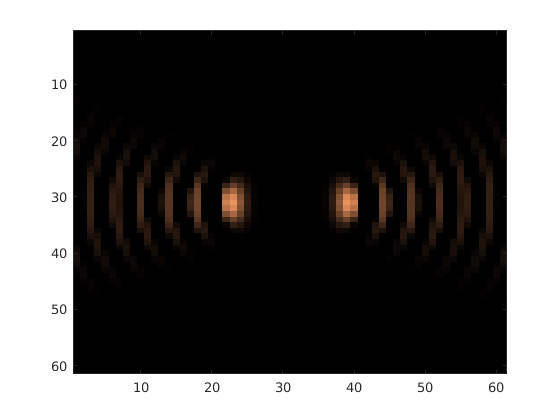

figure;
colorScale = mean(mean(imag(P(~isnan(P)))));
image(imag(P)/colorScale); colormap copper;

% colorScale = mean(mean(imag(p2(abs(p2) ~= inf))));
% image(imag(p2)/colorScale); colormap copper;
% title("Sound wave propagation at time T for source S2");

The result is not satisfying. We will try a different approach in he second part of this document.


$$P(r,\theta,\phi,k) = \sum_{l=0}^\infty \sum_{m=-l}^l C_{lm}(k)j_l(kr)Y_{lm}(\theta,\phi)$$


### Function deklaration

function y = myDot(k,r)
    y = k(1).*r(1,:) + k(2).*r(2,:) + k(3).*r(3,:);
end